## Alpha3 filters

The Alpha3 provides two filters in series:

- A resonant low-pass filter with adjustable steepness

- A high-pass filter

### Low-pass filter

#### Cutoff frequency

The filter is designed to have a cutoff frequency $F_c \in \left\lbrack 10,20000\right\rbrack$. The rationale for having a minimum value lower than 20Hz is the balance with the steepness.

For perceptive reason, the parameter defining $F_c$ is not linear, but rather logarithmic, with the possiblity to fine tune in the most common frequencies (something between 200 and 2000Hz).

A possible design is to compute $F_c$ using three tunable segments:

- Grow fast in the frequency range [0,200]

- Grow slowly in the range [200, 2000]

- Grow fast beyong 2000Hz

Which translates as:

- Let $S_1 =\lbrack 0,x_1 \rbrack$ be a first segment where the cutoff frequency grows from 0 to $F_1 =200\mathrm{Hz}$ quickly: $F_{S_1 } \left(x\right)=F_1 \;{\left(\frac{x}{r_1 }\right)}^2$

- Let $S_2 =\lbrack x_1 ,x_2 \rbrack$ be a second segment that finely tunes the cutoff frequencies betwen $F_1$ and $F_2$: $F_{S_2 } \left(x\right)=F_1 +F_2 \;\ln \left(1+\frac{x-x_1 }{r_2 }\right)$

- Let  $S_3 =\lbrack x_2 ,1\rbrack$ be a third segment where the cutoff frequency grows from $F_2$ to $F_3 =20000\mathrm{Hz}$ quickly: $F_{S_3 } \left(x\right)=F_2 +\left(F_3 -F_2 \right)\;{\left(\frac{x-x_2 }{r_3 }\right)}^2$

The three segments must output the same value on their borders, in other words: $F_{S_1 } \left(x_1 \right)=F_{S_2 } \left(x_1 \right)=F_1$ , $F_{S_2 } \left(x_2 \right)=F_{S_3 } \left(x_2 \right)=F_2$ and $F_{S_3 } \left(1\right)=F_3$.

- $F_{S_1 \left(x_1 \right)} =F_1 \Rightarrow {r_1 }^2 ={x_1 }^2$  implies $r_1 =x_1$ (since $r_1 >0$)

- 
$$F_{S_2 } \left(x_1 \right)=F_1 +F_2 \;\ln \left(1+\frac{x_1 -x_1 }{r_2 }\right)=F_1$$


- $F_{S_2 } \left(x_2 \right)=F_2 =F_1 +F_2 \;\ln \left(1+\frac{x_2 -x_1 }{r_2 }\right)\Rightarrow 1+\frac{x_2 -x_1 }{r_2 }=e^{\frac{F_2 -F_1 }{F_2 }} \Rightarrow x_2$ implies $r_2 =\frac{x_2 -x_1 }{e^{\tau } -1}\;,\tau =\frac{F_2 -F_1 }{F_2 }\;$

- 
$$F_{S_3 } \left(x_2 \right)=F_2 +\left(F_3 -F_2 \right)\;{\left(\frac{x-x_2 }{r_3 }\right)}^2 =F_2$$


- $F_{S_3 } \left(1\right)=F_2 +\left(F_3 -F_2 \right)\;{\left(\frac{1-x_2 }{r_3 }\right)}^2 =F_3 \Rightarrow {\left(\frac{1-x_2 }{r_3 }\right)}^2 =1$ implies $r_3 =1-x_2 \;$(since $r_3 >0$)

TODO

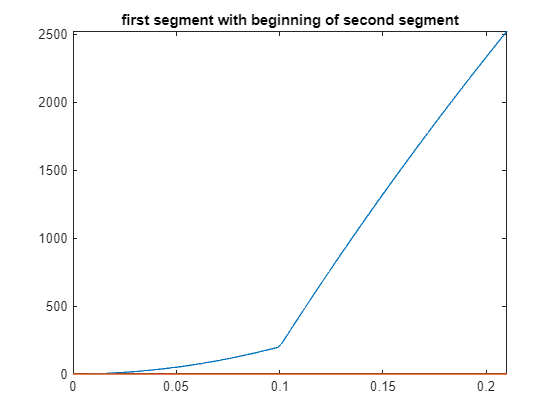

function y = get_freq(x)
    F1 = 200;
    x1 = 0.1;
    r1 = x1;
    F2 = 10000;
    x2 = 0.8;
    tau = (F2 - F1) / F2;
    r2 = (x2 - x1) / (exp(tau) - 1);
    F3 = 20000;
    r3 = 1-x2;
    if (x < x1)
        y = F1 * power(x / r1, 2);
    elseif (x < x2)
        y = F1 + F2 * log(1 + (x - x1) / r2);
        %y = F1 + F2 * log(1 + (x - x1) / 0.345);
    else
        y = F2 + (F3 - F2) * power((x - x2) / r3, 2);
    end
end
function plot_range(xmin, xmax, plot_title)
    c = linspace(xmin, xmax, 128);
    fc = zeros(128);
    for i = 1:128
        x = c(i);
        fc(i) = get_freq(x);

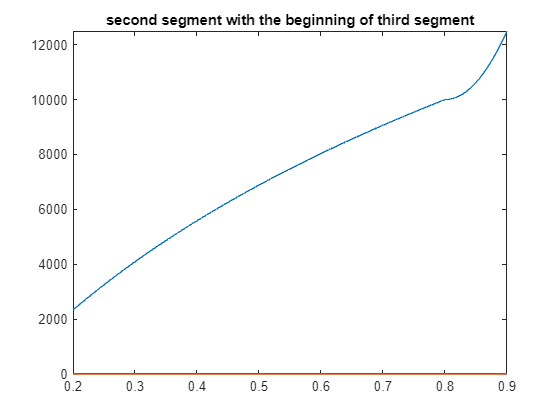

    end

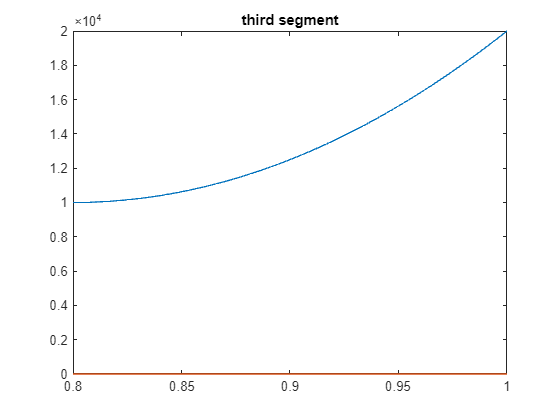

    ymin = min(fc, [], "all");

    ymax = max(fc, [], "all");
    plot(c, fc);
    xlim([xmin, xmax]);
    ylim([ymin ymax]);
    title(plot_title);
end
plot_range(0, 0.21, "first segment with beginning of second segment");
plot_range(0.2, 0.9, "second segment with the beginning of third segment");
plot_range(0.8, 1, "third segment");

#### Resonance

TODO

### High-pass filter

TODO